Wdw = 2; % pixel; nearest neigbourgh;
dataset_1 = 2; % Dataset of the original data
Window_1 = 0.5; % min; peak width at base in the original data
dataset_2 = 5; % derivative dataset
Window_2 = 0.1; % min; peak width at base in the derivative dataset

XY = myFinnee.getProfile(5, 'Total_Ions_Profile').Data;
XY(XY(:, 1) == 0, :) = [];
LM = LocalMaxima(XY, 2, 0);

IStart = 1;
IMax = findCloser(XY(:, 1), LM(1,1));
IdStart = find(XY(IStart:IMax, 2) == min(XY(IStart:IMax, 2)), 1, 'last') + IStart -1;
IEnd = findCloser(XY(:, 1), LM(2,1));
IdEnd = find(XY(IMax:IEnd, 2) == min(XY(IMax:IEnd, 2)), 1, 'last') + IMax -1;

pIMin = findCloser(XY(:, 1), LM(1,1)-Window_2);
pIMax =  findCloser(XY(:, 1), LM(1,1)+Window_2);
figure
nexttile
plot(XY(pIMin:pIMax, 1), XY(pIMin:pIMax, 2));
hold on
p = area(XY(IdStart:IdEnd, 1), XY(IdStart:IdEnd, 2))

p =   Area with properties:

    FaceColor: [0.8500 0.3250 0.0980]
    EdgeColor: [0 0 0]
    LineStyle: '-'
    LineWidth: 0.5000
    BaseValue: 0
        XData: [3.1260 3.1305 3.1350 3.1395 3.1440 3.1485 3.1530]
        YData: [1.4841e-04 1.5425e-04 1.9115e-04 2.5169e-04 2.8132e-04 2.4823e-04 2.4250e-04]

  Show all properties


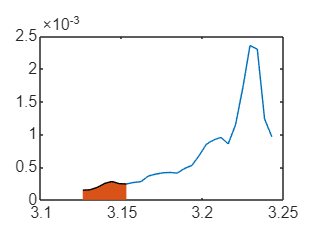

hold off